### Primero Cargamos los datos 

load("DATOS\twosat\Mediterraneo\Data_Anticiclonica_short_long_combinado.mat")
load("DATOS\twosat\Mediterraneo\Data_Cicllonica_short_long_combinado.mat")
% Show variables (fields) of the struct
fields = fieldnames(Data_ANC);

tipos={"Data_ANC","Data_CIC"};

### Representación por separado respecto lifetime Grafico Ciclonicos y Anticiclonicos

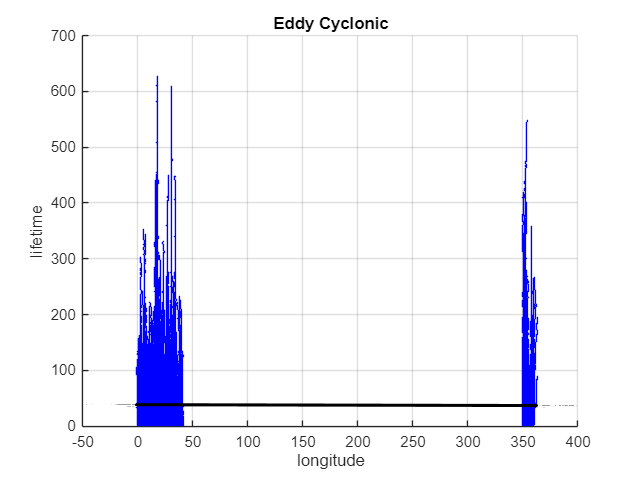

SelectTipo=tipos(2); 
if SelectTipo{1}=="Data_ANC"
    Titulo="Eddy Anticyclonic";
    color="red";
elseif SelectTipo{1}=="Data_CIC"
    Titulo="Eddy Cyclonic";
    color="blue";
end

SelectVariableY=fields(29);  AnCiclonY= eval(SelectTipo{1}).(SelectVariableY{1}) ;    % VARIABLE A REPRESENTAR 
SelectVariableX=fields(12);  AnCiclonX=eval(SelectTipo{1}).(SelectVariableX{1}) ;

scatter(AnCiclonX,AnCiclonY,1, 'filled','MarkerFaceColor', color)  
hold on

% Calcular la regresión lineal
p = polyfit(AnCiclonX, AnCiclonY, 1); % Ajuste de primer grado (lineal)
yFit = polyval(p, AnCiclonX); % Evaluar la función ajustada

% Graficar la línea de regresión
plot(AnCiclonX, yFit, 'black-', 'LineWidth', 2)
hold off
grid on
title(Titulo)
xlabel(SelectVariableX{1})
ylabel(SelectVariableY{1})

### Representación frecuencia LifetimeMax Grafico Ciclonicos y Anticiclonicos

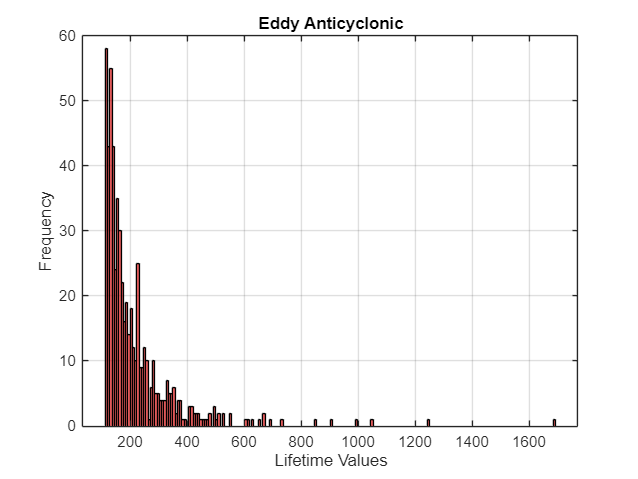

SelectTipo=tipos(1); 
if SelectTipo{1}=="Data_ANC"
    Titulo="Eddy Anticyclonic";
    color="red";
elseif SelectTipo{1}=="Data_CIC"
    Titulo="Eddy Cyclonic";
    color="blue";
end

% Get unique tracks
Lifetime = eval(SelectTipo{1}).lifetime;
Tracks = eval(SelectTipo{1}).track;
uniqueTracks = unique(Tracks);  % Find unique track values

% Loop through each unique track value
newLifetime = [];  % Array to store the modified lifetime values
for j = uniqueTracks'
    % Find the indices where the track is equal to the current unique track value
    idx = find(Tracks == j);
    life = Lifetime(idx);  % Extract the lifetime values for this track
    vida_max = max(life); 
    if vida_max>7*16% Find the maximum lifetime for this track
     newLifetime = [newLifetime, vida_max];  % Append the maximum lifetime to the newLifetime array
    end
end

% Now you can use newLifetime to plot or further process the data
% Example of plotting a histogram:
histogram(newLifetime, 200, 'FaceColor', color, 'EdgeColor', 'k');
xlabel('Lifetime');
ylabel('Frequency');
title(Titulo);
grid on;